# Calcolo Cinematica Diretta Con Parametri Di Denavit-Hartenberg

L'obiettivo della cinematica diretta è determinare la posizione e l'orientamento dell'organo terminale (end-effector) a partire dai valori delle variabili di giunto. Si utilizza la convenzione di Denavit-Hartenberg (DH) per modellare la geometria del robot. La convenzione di Denavit-Hartenberg è un metodo standard per assegnare sistemi di riferimento ai bracci di un robot. Per ogni braccio, si definiscono quattro parametri che descrivono la trasformazione geometrica rispetto al braccio precedente.

Si inizia definendo le variabili simboliche necessarie per i parametri DH. Questo permette di eseguire i calcoli in forma generale, senza dover specificare subito valori numerici. Successivamente, si assemblano questi parametri in una tabella dove ogni riga corrisponde a un giunto del robot e le colonne rappresentano i parametri $\left(\begin{array}{c} \theta ,d,\alpha ,a \end{array}\right)$.

clc; clear; close all;

% Definizione Variabili Simboliche
syms q1 q2 q3 d1 d2 d3 alpha1 alpha2 alpha3 a1 a2 a3 real;

% Tabella Parametri Denavit-Hartenberg (DH)
DH_table = [q1, 0, -pi/2, 0;
            q2, 0, pi/2, 0;
            q3, d3, 0, 0];


% Numero Giunti Manipolatore
n = size(DH_table, 1);

A partire dalla tabella DH, si può calcolare la matrice di trasformazione omogenea $A_i$ per ciascun giunto $i$. Questa matrice, di dimensioni $4\times 4$, rappresenta la trasformazione (rotazione e traslazione) dal sistema di riferimento del giunto $i$ a quello del giunto $i-1$. Si utilizza la funzione `Compute_DH_Transformations`per generare le matrici simboliche per ogni riga della tabella DH.

[T_matrices, R_matrices] = Compute_DH_Transformations(DH_table);

j = 3;
for i = 1:n
    fprintf('Matrice Di Trasformazione Omogenea ^(%d)T_(%d):\n', j, j+1);
    disp(T_matrices(:,:,i));

    j = j+1;
end

Matrice Di Trasformazione Omogenea ^(3)T_(4):


$$\left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & -\sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & 0 & \cos\left(q_{1}\right) & 0\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matrice Di Trasformazione Omogenea ^(4)T_(5):


$$\left(\begin{array}{cccc} \cos\left(q_{2}\right) & 0 & \sin\left(q_{2}\right) & 0\\ \sin\left(q_{2}\right) & 0 & -\cos\left(q_{2}\right) & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matrice Di Trasformazione Omogenea ^(5)T_(6):


$$\left(\begin{array}{cccc} \cos\left(q_{3}\right) & -\sin\left(q_{3}\right) & 0 & 0\\ \sin\left(q_{3}\right) & \cos\left(q_{3}\right) & 0 & 0\\ 0 & 0 & 1 & d_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T36 = T_matrices(:,:,1) * T_matrices(:,:,2) * T_matrices(:,:,3);
T36 = simplify(T36);

fprintf('Matrice Di Trasformazione Omogenea ^{3}T_(6):\n');

Matrice Di Trasformazione Omogenea ^{3}T_(6):


disp(T36);

$$\left(\begin{array}{cccc} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\sin\left(q_{1}\right)\,\sin\left(q_{3}\right) & -\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)-\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right) & \cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & d_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \cos\left(q_{1}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{3}\right)-\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & d_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ -\cos\left(q_{3}\right)\,\sin\left(q_{2}\right) & \sin\left(q_{2}\right)\,\sin\left(q_{3}\right) & \cos\left(q_{2}\right) & d_{3}\,\cos\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

La matrice di trasformazione omogenea totale $^3 T_6$ contiene tutte le informazioni sulla posa dell'organo terminale. Da essa possiamo estrarre due elementi chiave:

- La **matrice di rotazione R**, che definisce l'orientamento dell'organo terminale rispetto alla base. Corrisponde alla sottomatrice 3x3 in alto a sinistra.

- Il **vettore di posizione p**, che indica la posizione dell'origine del sistema di riferimento dell'organo terminale. Corrisponde alle prime tre righe della quarta colonna.

% Estrazione Vettore Posizione
p36 = T36(1:3, 4);
p36 = simplify(p36);
fprintf('Vettore Posizione p36:\n');

Vettore Posizione p36:


disp(p36);

$$\left(\begin{array}{c} d_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ d_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ d_{3}\,\cos\left(q_{2}\right) \end{array}\right)$$

% Estrazione Matrice Rotazione
R36 = T36(1:3, 1:3);
R36 = simplify(R36);
fprintf('Matrice Rotazione R36:\n');

Matrice Rotazione R36:


disp(R36);

$$\left(\begin{array}{ccc} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\sin\left(q_{1}\right)\,\sin\left(q_{3}\right) & -\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)-\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right) & \cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \cos\left(q_{1}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{3}\right)-\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ -\cos\left(q_{3}\right)\,\sin\left(q_{2}\right) & \sin\left(q_{2}\right)\,\sin\left(q_{3}\right) & \cos\left(q_{2}\right) \end{array}\right)$$

Per visualizzare una configurazione specifica del robot sono necessari dei valori numerici. Si sostituiscono ora le variabili simboliche (angoli di giunto e parametri geometrici) con valori numerici.

% Lista Variabili Simboliche
symsList = symvar(T_matrices);
disp('Variabili Simboliche:');

Variabili Simboliche:


disp(symsList);

$$\left(\begin{array}{cccc} d_{3} & q_{1} & q_{2} & q_{3} \end{array}\right)$$

% Valori Numerici Da Sostituire
value = [0.5, pi/4, pi/2, pi/3];

% La sostituzione su un array 3D simbolico può essere problematica.
% È più sicuro sostituire i valori matrice per matrice.
T_Num = zeros(4,4,n);
for i = 1:n
    T_Num(:,:,i) = subs(T_matrices(:,:,i), symsList, value);
end

% Stampa Matrici Numeriche
for i = 1:n
    fprintf('Matrice ^(%d)T_(%d) numerica:\n', i+2, i+3);
    disp(T_Num(:,:,i));
end

Matrice ^(3)T_(4) numerica:


    0.7071         0   -0.7071         0
    0.7071         0    0.7071         0
         0   -1.0000         0         0
         0         0         0    1.0000



Matrice ^(4)T_(5) numerica:


     0     0     1     0
     1     0     0     0
     0     1     0     0
     0     0     0     1



Matrice ^(5)T_(6) numerica:


    0.5000   -0.8660         0         0
    0.8660    0.5000         0         0
         0         0    1.0000    0.5000
         0         0         0    1.0000



## Visualizzazione Grafica

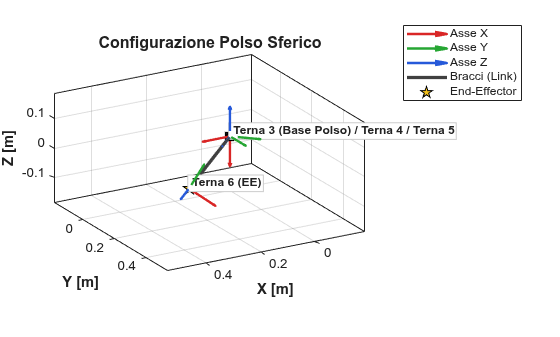

fig_name    = 'Configurazione Polso Sferico';
arrow_scale = 0.10;
view_angles = [150, 20];
labels      = {'Terna 3 (Base Polso)', 'Terna 4', 'Terna 5', 'Terna 6 (EE)'};

figure('Name', fig_name, 'Color', 'w');
hold on;
grid on;
box on;
xlabel('X [m]', 'FontWeight', 'bold');
ylabel('Y [m]', 'FontWeight', 'bold');
zlabel('Z [m]', 'FontWeight', 'bold');
view(view_angles(1), view_angles(2));
axis equal;

% 1. Calcolo di Tutte le Posizioni e Orientamenti (Base + n Giunti)
T_cumulative = eye(4);
positions = zeros(n+1, 3);
R_all     = zeros(3, 3, n+1);

positions(1, :) = T_cumulative(1:3, 4).';
R_all(:, :, 1)  = T_cumulative(1:3, 1:3);

for i = 1:n
    T_cumulative = T_cumulative * double(T_Num(:, :, i));
    positions(i+1, :) = T_cumulative(1:3, 4).';
    R_all(:, :, i+1)  = T_cumulative(1:3, 1:3);
end

% 2. Disegno dello Scheletro Meccanico (Bracci)
h_link = plot3(positions(:,1), positions(:,2), positions(:,3), '-', ...
    'Color', [0.25 0.25 0.25], 'LineWidth', 2.5);

% 3. Evidenziazione Giunti Meccanici ed End-Effector
h_base = plot3(positions(1,1), positions(1,2), positions(1,3), 's', ...
    'MarkerSize', 8, 'MarkerFaceColor', [0.4 0.4 0.4], 'MarkerEdgeColor', 'k');
h_joints = plot3(positions(2:end-1,1), positions(2:end-1,2), positions(2:end-1,3), 'o', ...
    'MarkerSize', 6, 'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'k');
h_ee = plot3(positions(end,1), positions(end,2), positions(end,3), 'p', ...
    'MarkerSize', 10, 'MarkerFaceColor', [0.95 0.75 0.1], 'MarkerEdgeColor', 'k');

% 4. Disegno delle Terne di Riferimento DH (X=Rosso, Y=Verde, Z=Blu)
col_X = [0.85, 0.15, 0.15];
col_Y = [0.15, 0.65, 0.20];
col_Z = [0.15, 0.35, 0.85];

h_axes = gobjects(1, 3);
for i = 1:(n+1)
    p = positions(i, :);
    R = R_all(:, :, i);
    
    qx = quiver3(p(1), p(2), p(3), R(1,1)*arrow_scale, R(2,1)*arrow_scale, R(3,1)*arrow_scale, 0, ...
        'Color', col_X, 'LineWidth', 1.8, 'MaxHeadSize', 0.35);
    qy = quiver3(p(1), p(2), p(3), R(1,2)*arrow_scale, R(2,2)*arrow_scale, R(3,2)*arrow_scale, 0, ...
        'Color', col_Y, 'LineWidth', 1.8, 'MaxHeadSize', 0.35);
    qz = quiver3(p(1), p(2), p(3), R(1,3)*arrow_scale, R(2,3)*arrow_scale, R(3,3)*arrow_scale, 0, ...
        'Color', col_Z, 'LineWidth', 1.8, 'MaxHeadSize', 0.35);
    
    if i == 1
        h_axes(1) = qx;
        h_axes(2) = qy;
        h_axes(3) = qz;
    end
end

% 5. Etichette Intelligenti con Raggruppamento Origini Coincidenti
visited = false(n+1, 1);
for i = 1:(n+1)
    if visited(i)
        continue;
    end
    dists = sqrt(sum((positions - positions(i, :)).^2, 2));
    coincident_idx = find(dists < 1e-4);
    visited(coincident_idx) = true;
    combined_label = strjoin(labels(coincident_idx), ' / ');
    p = positions(i, :);
    text(p(1), p(2), p(3) + 0.18*arrow_scale, sprintf(' %s', combined_label), ...
        'FontSize', 9, 'FontWeight', 'bold', ...
        'BackgroundColor', [1 1 1], 'EdgeColor', [0.8 0.8 0.8], 'Margin', 1);
end

% 6. Margine di Visualizzazione Attorno al Robot
all_pts = [positions; positions + arrow_scale; positions - arrow_scale];
min_xyz = min(all_pts, [], 1);
max_xyz = max(all_pts, [], 1);
span = max(max_xyz - min_xyz);
if span == 0, span = 1; end
margin = 0.15 * span;
xlim([min_xyz(1) - margin, max_xyz(1) + margin]);
ylim([min_xyz(2) - margin, max_xyz(2) + margin]);
zlim([min_xyz(3) - margin, max_xyz(3) + margin]);

% 7. Legenda e Titolo
legend([h_axes(1), h_axes(2), h_axes(3), h_link, h_ee], ...
    {'Asse X', 'Asse Y', 'Asse Z', 'Bracci (Link)', 'End-Effector'}, ...
    'Location', 'bestoutside');
title(fig_name, 'FontSize', 12, 'FontWeight', 'bold');
hold off;